# Savitzky-Golay Filtering

A program which is developed based on Savitzky-Golay approach for smoothing rate-normalized pressure (RNP) data.

Author: Munthe, Felix A.

Created on Monday, 30 October 2023

## Import Data

### True RNP Data

clear; clc; clf;
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
true_RNP = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\true_RNP.txt", opts)

true_RNP = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


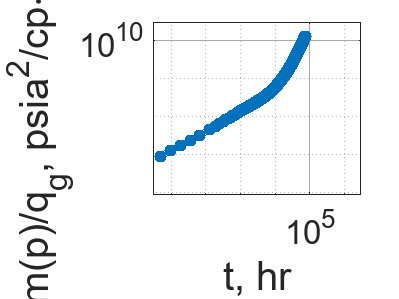


% Plot
loglog(true_RNP.t, true_RNP.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("True RNP Data", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

### Noisy RNP Data Set 185

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
noisy_RNP_185 = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\Noisy RNP Model\All\25%\noisy_data_5.txt", opts)

noisy_RNP_185 = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    6.1827e+07
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    1.0956e+08
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    2.2588e+08
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


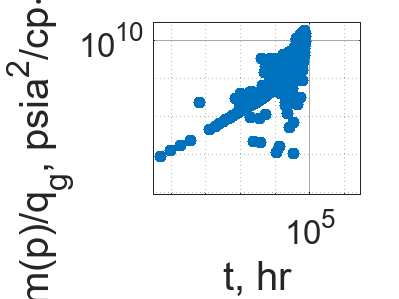


% Plot
loglog(noisy_RNP_185.t, noisy_RNP_185.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("Noisy RNP Data Set 185", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

## Smoothing

### Noisy RNP Data 185

logRNP_185 = log(noisy_RNP_185.RNP);

#### Window: 3

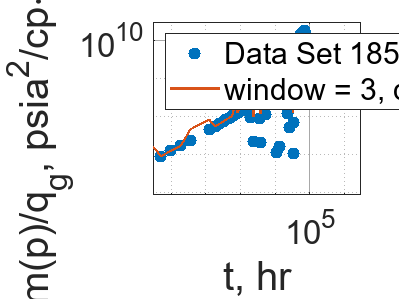

% Plot
loglog(noisy_RNP_185.t, noisy_RNP_185.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 185");
% title("Noisy RNP Data Set 185", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_185_31 = smooth(logRNP_185, 3, "sgolay", 1);
smoothedRNP_185_31 = exp(smoothedLogRNP_185_31);
residual_185_31 = (true_RNP.RNP - smoothedRNP_185_31) ./ (0.3413 .* true_RNP.RNP);
sse_185_31 = sum(residual_185_31 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_31, "-", "LineWidth", 1.3, "DisplayName", "window = 3, degree = 1");
legend("Location", "northwest");
hold off;

### Window: 5

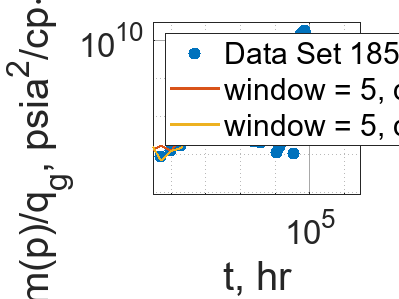

% Plot
loglog(noisy_RNP_185.t, noisy_RNP_185.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 185");
% title("Noisy RNP Data Set 185", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_185_51 = smooth(logRNP_185, 5, "sgolay", 1);
smoothedRNP_185_51 = exp(smoothedLogRNP_185_51);
residual_185_51 = (true_RNP.RNP - smoothedRNP_185_51) ./ (0.3413 .* true_RNP.RNP);
sse_185_51 = sum(residual_185_51 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_51, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_185_52 = smooth(logRNP_185, 5, "sgolay", 2);
smoothedRNP_185_52 = exp(smoothedLogRNP_185_52);
residual_185_52 = (true_RNP.RNP - smoothedRNP_185_52) ./ (0.3413 .* true_RNP.RNP);
sse_185_52 = sum(residual_185_52 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_52, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 2");
legend("Location", "northwest");
hold off;

#### Window: 7

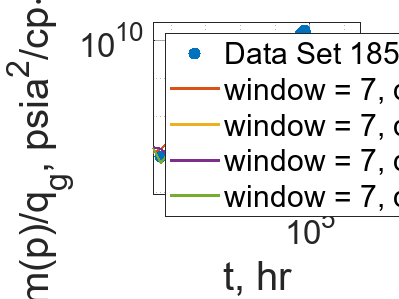

% Plot
loglog(noisy_RNP_185.t, noisy_RNP_185.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 185");
% title("Noisy RNP Data Set 185", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_185_71 = smooth(logRNP_185, 7, "sgolay", 1);
smoothedRNP_185_71 = exp(smoothedLogRNP_185_71);
residual_185_71 = (true_RNP.RNP - smoothedRNP_185_71) ./ (0.3413 .* true_RNP.RNP);
sse_185_71 = sum(residual_185_71 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_71, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_185_72 = smooth(logRNP_185, 7, "sgolay", 2);
smoothedRNP_185_72 = exp(smoothedLogRNP_185_72);
residual_185_72 = (true_RNP.RNP - smoothedRNP_185_72) ./ (0.3413 .* true_RNP.RNP);
sse_185_72 = sum(residual_185_72 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_72, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_185_73 = smooth(logRNP_185, 7, "sgolay", 3);
smoothedRNP_185_73 = exp(smoothedLogRNP_185_73);
residual_185_73 = (true_RNP.RNP - smoothedRNP_185_73) ./ (0.3413 .* true_RNP.RNP);
sse_185_73 = sum(residual_185_73 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_73, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_185_74 = smooth(logRNP_185, 7, "sgolay", 4);
smoothedRNP_185_74 = exp(smoothedLogRNP_185_74);
residual_185_74 = (true_RNP.RNP - smoothedRNP_185_74) ./ (0.3413 .* true_RNP.RNP);
sse_185_74 = sum(residual_185_74 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_74, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 4");
legend("Location", "northwest");
hold off;

#### Window: 9

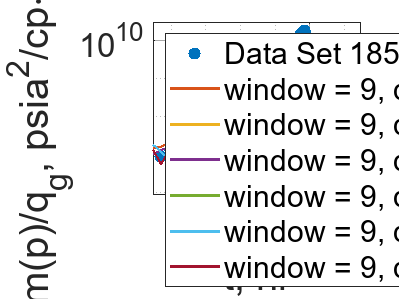

% Plot
loglog(noisy_RNP_185.t, noisy_RNP_185.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 185");
% title("Noisy RNP Data Set 185", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_185_91 = smooth(logRNP_185, 9, "sgolay", 1);
smoothedRNP_185_91 = exp(smoothedLogRNP_185_91);
residual_185_91 = (true_RNP.RNP - smoothedRNP_185_91) ./ (0.3413 .* true_RNP.RNP);
sse_185_91 = sum(residual_185_91 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_91, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_185_92 = smooth(logRNP_185, 9, "sgolay", 2);
smoothedRNP_185_92 = exp(smoothedLogRNP_185_92);
residual_185_92 = (true_RNP.RNP - smoothedRNP_185_92) ./ (0.3413 .* true_RNP.RNP);
sse_185_92 = sum(residual_185_92 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_92, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_185_93 = smooth(logRNP_185, 9, "sgolay", 3);
smoothedRNP_185_93 = exp(smoothedLogRNP_185_93);
residual_185_93 = (true_RNP.RNP - smoothedRNP_185_93) ./ (0.3413 .* true_RNP.RNP);
sse_185_93 = sum(residual_185_93 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_93, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_185_94 = smooth(logRNP_185, 9, "sgolay", 4);
smoothedRNP_185_94 = exp(smoothedLogRNP_185_94);
residual_185_94 = (true_RNP.RNP - smoothedRNP_185_94) ./ (0.3413 .* true_RNP.RNP);
sse_185_94 = sum(residual_185_94 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_94, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_185_95 = smooth(logRNP_185, 9, "sgolay", 5);
smoothedRNP_185_95 = exp(smoothedLogRNP_185_95);
residual_185_95 = (true_RNP.RNP - smoothedRNP_185_95) ./ (0.3413 .* true_RNP.RNP);
sse_185_95 = sum(residual_185_95 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_95, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_185_96 = smooth(logRNP_185, 9, "sgolay", 6);
smoothedRNP_185_96 = exp(smoothedLogRNP_185_96);
residual_185_96 = (true_RNP.RNP - smoothedRNP_185_96) ./ (0.3413 .* true_RNP.RNP);
sse_185_96 = sum(residual_185_96 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_96, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 6");
legend("Location", "northwest");
hold off;

#### Window: 11

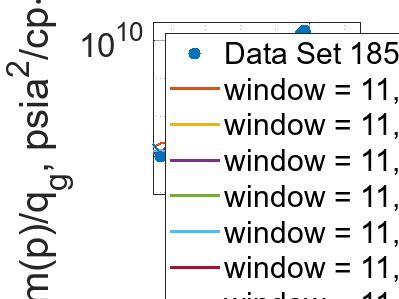

% Plot
loglog(noisy_RNP_185.t, noisy_RNP_185.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 185");
% title("Noisy RNP Data Set 185", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_185_111 = smooth(logRNP_185, 11, "sgolay", 1);
smoothedRNP_185_111 = exp(smoothedLogRNP_185_111);
residual_185_111 = (true_RNP.RNP - smoothedRNP_185_111) ./ (0.3413 .* true_RNP.RNP);
sse_185_111 = sum(residual_185_111 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_111, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_185_112 = smooth(logRNP_185, 11, "sgolay", 2);
smoothedRNP_185_112 = exp(smoothedLogRNP_185_112);
residual_185_112 = (true_RNP.RNP - smoothedRNP_185_112) ./ (0.3413 .* true_RNP.RNP);
sse_185_112 = sum(residual_185_112 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_112, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_185_113 = smooth(logRNP_185, 11, "sgolay", 3);
smoothedRNP_185_113 = exp(smoothedLogRNP_185_113);
residual_185_113 = (true_RNP.RNP - smoothedRNP_185_113) ./ (0.3413 .* true_RNP.RNP);
sse_185_113 = sum(residual_185_113 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_113, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_185_114 = smooth(logRNP_185, 11, "sgolay", 4);
smoothedRNP_185_114 = exp(smoothedLogRNP_185_114);
residual_185_114 = (true_RNP.RNP - smoothedRNP_185_114) ./ (0.3413 .* true_RNP.RNP);
sse_185_114 = sum(residual_185_114 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_114, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_185_115 = smooth(logRNP_185, 11, "sgolay", 5);
smoothedRNP_185_115 = exp(smoothedLogRNP_185_115);
residual_185_115 = (true_RNP.RNP - smoothedRNP_185_115) ./ (0.3413 .* true_RNP.RNP);
sse_185_115 = sum(residual_185_115 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_115, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_185_116 = smooth(logRNP_185, 11, "sgolay", 6);
smoothedRNP_185_116 = exp(smoothedLogRNP_185_116);
residual_185_116 = (true_RNP.RNP - smoothedRNP_185_116) ./ (0.3413 .* true_RNP.RNP);
sse_185_116 = sum(residual_185_116 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_116, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 6");
hold on;

% Degree = 7
smoothedLogRNP_185_117 = smooth(logRNP_185, 11, "sgolay", 7);
smoothedRNP_185_117 = exp(smoothedLogRNP_185_117);
residual_185_117 = (true_RNP.RNP - smoothedRNP_185_117) ./ (0.3413 .* true_RNP.RNP);
sse_185_117 = sum(residual_185_117 .^ 2);
loglog(noisy_RNP_185.t, smoothedRNP_185_117, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 7");
legend("Location", "northwest");
hold off;